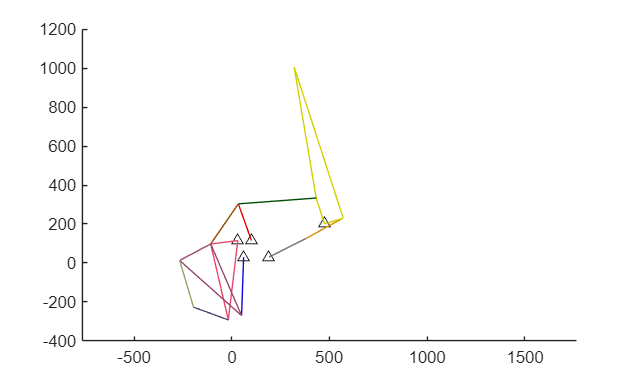

clear; close all; clc;
theta2 = sym('theta2');
theta4 = sym('theta4');
theta7 = sym('theta7');
assume(theta7-deg2rad(56),'positive');
assume(deg2rad(99)-theta7,'positive');
theta9 = sym('theta9');
theta8 = sym('theta8');

O3x = 190; O3y = 30;
O4x = 475; O4y = 200;
O7x = 100; O7y = 115;
O9x = 30; O9y = 115;
O8x = 60; O8y = 30;

L2 = 210;  
L3 = 220;  
L4_long = 815;  
L4_short = 140;
L4_height = 100;
L5 = 400; 
L6 = 250; 
L7 = 200;  
tri9 = [140, 400, 410];  
tri10 = [180, 425, 400]; 
L11 = 250;   
L12 = 190;   
L8 = 300;     

theta3 = sym('theta3');  theta5 = sym('theta5'); theta6 = sym('theta6');
theta10 = sym('theta10'); theta11 = sym('theta11'); theta12 = sym('theta12');

% four bar 4 5 7
Cx = O4x + L4_short * cos(theta4);
Cy = O4y + L4_short * sin(theta4);
Dx = O7x + L7*cos(theta7);
Dy = O7y + L7*sin(theta7);
eq3 = Cx == Dx + L5*cos(theta5);
eq4 = Cy == Dy + L5*sin(theta5);
sol2 = solve([eq3 eq4],[theta5 theta4]);
CxNew = subs(Cx, theta4, sol2.theta4(1));
CyNew = subs(Cy, theta4, sol2.theta4(1));

% four bar 2 3 4
Ax = O3x + L2*cos(theta2);
Ay = O3y + L2*sin(theta2);
Bx = O4x+L4_height*cos(sol2.theta4(1)-deg2rad(90));
By = O4y+L4_height*sin(sol2.theta4(1)-deg2rad(90));
eq1 = Ax == Bx + L3*cos(theta3);
eq2 = Ay == By + L3*sin(theta3);
sol1 = solve([eq1 eq2],[theta3 theta2]);
AxNew = subs(Ax,theta2,sol1.theta2(2));
AyNew = subs(Ay,theta2,sol1.theta2(2));

% four bar 7 6 9
Fx = O9x + tri9(1)*cos(theta9);
Fy = O9y + tri9(1)*sin(theta9);
eq5 = Fx == Dx + L6*cos(theta6);
eq6 = Fy == Dy + L6*sin(theta6);
sol3 = solve([eq5 eq6], [theta6 theta9]);
FxNew = subs(Fx, theta9, sol3.theta9(2));
FyNew = subs(Fy, theta9, sol3.theta9(2));

% four bar 9 10 8

Hx = O8x + L8*cos(theta8);
Hy = O8y + L8*sin(theta8);
eq7 = Hx == FxNew + tri10(3)*cos(theta10);
eq8 = Hy == FyNew + tri10(3)*sin(theta10);
sol4 = solve([eq7 eq8], [theta10 theta8]);
HxNew = subs(Hx, theta8, sol4.theta8(1));
HyNew = subs(Hy, theta8, sol4.theta8(1));

Kx = O9x + tri9(3)*cos(sol3.theta9(2)+deg2rad(76.037));
Ky = O9y + tri9(3)*sin(sol3.theta9(2)+deg2rad(76.037));
Ix = FxNew + tri10(1)*cos(sol4.theta10(1)-deg2rad(85.31));
Iy = FyNew + tri10(1)*sin(sol4.theta10(1)-deg2rad(85.31));
Jx = Ix + L11*cos(theta11);
Jy = Iy + L11*sin(theta11);
eq9 = Jx == Kx + L12*cos(theta12);
eq10 = Jy == Ky + L12*sin(theta12);
sol5 = solve([eq9 eq10], [theta11 theta12]);
JxNew = subs(Jx, theta11, sol5.theta11(2));
JyNew = subs(Jy, theta11, sol5.theta11(2));

Mx = Bx + L4_long*cos(sol2.theta4(1));
My = By + L4_long*sin(sol2.theta4(1));

%plot

h_link2 = @(t) plot([O3x subs(AxNew,t)], [O3y subs(AyNew,t)], 'Color', [108, 108, 108]/255);
h_link3 = @(t) plot([subs(AxNew,t) subs(Bx ,t)], [subs(AyNew,t) subs(By ,t)], 'Color', [217, 137, 0]/255);
h_link4 = @(t) plot([O4x subs(CxNew,t) subs(Mx ,t) subs(Bx ,t) O4x], [O4y subs(CyNew,t) subs(My ,t) subs(By ,t) O4y], 'Color', [208, 209, 0]/255);
h_link5 = @(t) plot([subs(CxNew,t) subs(Dx ,t)], [subs(CyNew,t) subs(Dy ,t)], 'Color', [0, 76, 0]/255);
h_link7 = @(t) plot([O7x subs(Dx,t)], [O7y subs(Dy,t)], 'Color', [232, 0, 0]/255);
h_link6 = @(t) plot([subs(Dx,t) subs(FxNew,t)], [subs(Dy,t) subs(FyNew,t)],  'Color', [148, 70, 0]/255);
h_link9 = @(t) plot([O9x subs(FxNew,t) subs(Kx ,t) O9x], [O9y subs(FyNew,t) subs(Ky ,t) O9y], 'Color', [232, 70, 106]/255);
h_link10 = @(t) plot([subs(FxNew,t) subs(HxNew,t) subs(Ix ,t) subs(FxNew,t)], [subs(FyNew,t) subs(HyNew,t) subs(Iy ,t) subs(FyNew,t)], 'Color', [151, 70, 108]/255);
h_link8 = @(t) plot([O8x subs(HxNew,t)], [O8y subs(HyNew,t)], 'Color', [8, 6, 215]/255);
h_link11 = @(t) plot([subs(Ix ,t) subs(JxNew,t)], [subs(Iy ,t) subs(JyNew,t)], 'Color', [158, 158, 108]/255);
h_link12 = @(t) plot([subs(Kx ,t) subs(JxNew,t)], [subs(Ky ,t) subs(JyNew,t)], 'Color', [74, 74, 108]/255);


figure()
hold on
plot(O3x,O3y,"^k")
plot(O4x,O4y,"^k")
plot(O7x,O7y,"^k")
plot(O9x,O9y,"^k")
plot(O8x,O8y,"^k")

range = [deg2rad(51.345) deg2rad(110.073)]; %sym limit
%range = [deg2rad(56) deg2rad(99)]; %mech limit
frame = 120; % Define the frame rate for the animation
fanimator(h_link7,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link2,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link3,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link4,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link5,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link6,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link8,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link9,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link10,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link11,'AnimationRange', range,'FrameRate',frame)
fanimator(h_link12,'AnimationRange', range,'FrameRate',frame)
hold off
axis equal
playAnimation

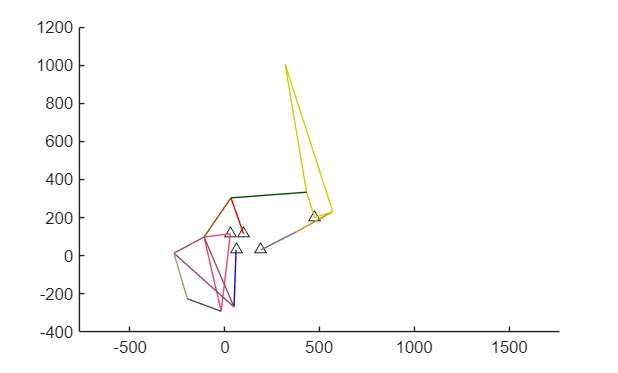

playAnimation